# Self-organizing maps

This demonstration presents examples of 1-dimensional and 2-dimensional self-organizing maps (SOM) which are created to represent the 2-dimensional input space.

Data for this example are defined as 4 clusters in 2-dimensional space, and then 1D and 2D SOM networks are created to represent this data space.

Self-organizing networks are based on competitive learning and trained SOM networks learn to recognize groups of similar input vectors in such a way that neurons physically near each other in the neuron layer respond to similar input vectors. 

2022 © Primož Potočnik ([University of Ljubljana](https://www.uni-lj.si), [Faculty of Mechanical Engineering](https://www.fs.uni-lj.si))

## Define 4 clusters of input data

Generate 4 clusters of 2-dimensional input data without any target classes.

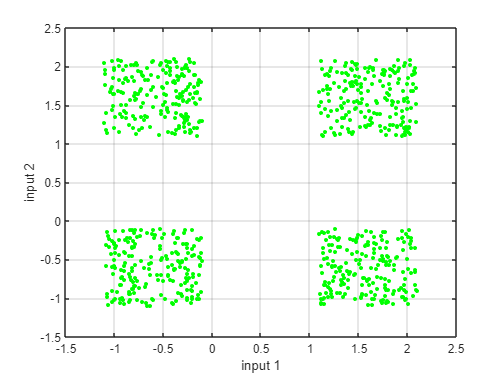

close all, clear all, clc, format compact

Ncluster =200; % number of samples of each cluster
offset   =1.1; % offset between clusters

 

% define 4 clusters of input data
P = [rand(1,Ncluster)-offset rand(1,Ncluster)+offset rand(1,Ncluster)+offset rand(1,Ncluster)-offset;
     rand(1,Ncluster)+offset rand(1,Ncluster)+offset rand(1,Ncluster)-offset rand(1,Ncluster)-offset];

% plot clusters
plot(P(1,:),P(2,:),'g.','MarkerSize',10)
hold on, grid on
xlabel('input 1')
ylabel('input 2')

## Create and train 1D-SOM

Create 1-dimensional SOM to approximate the 2-dimensional data. MATLAB built-in function 'selforgmap' is applied to create SOM network.

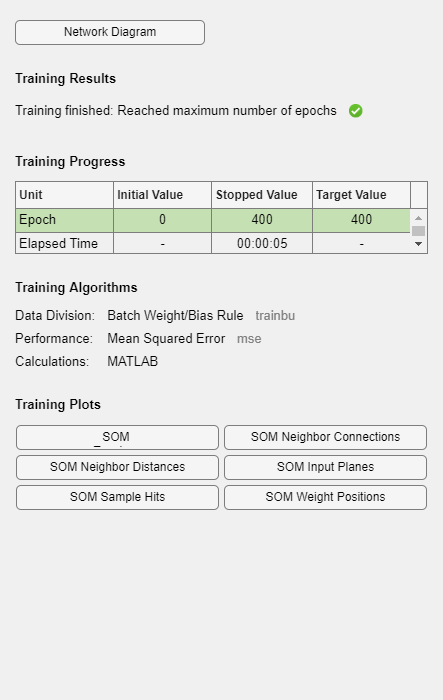

% SOM parameters
dimensions   =70; % SOM dimensions
topologyFcn  = "hextop";      % topology function
distanceFcn  = "dist";      % distance function
initNeighbor =5;  % initial neighborhood size
coverSteps   =200; % number of training steps for initial covering

 

% define 1D net
net1 = selforgmap(dimensions,coverSteps,initNeighbor,topologyFcn,distanceFcn);

% train
[net1,Y] = train(net1,P);

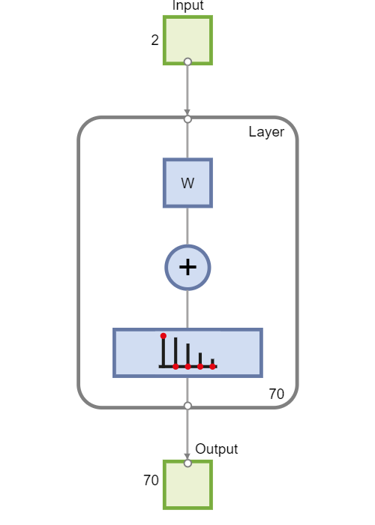

% view net
view(net1)

**Plot 1D-SOM result**

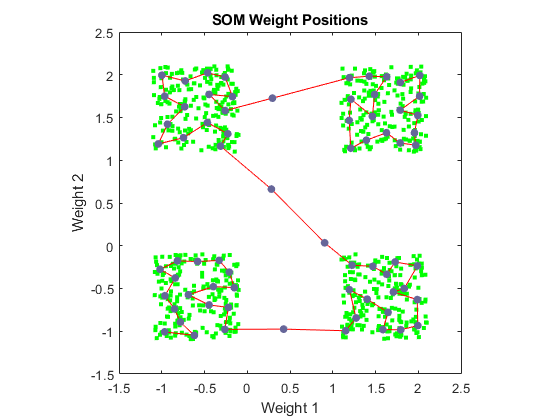

% plot input data and SOM weight positions
plotsompos(net1,P);

## Create and train 2D-SOM

Create 2-dimensional SOM to approximate the 2-dimensional data. MATLAB built-in function 'selforgmap' is applied to create SOM network.

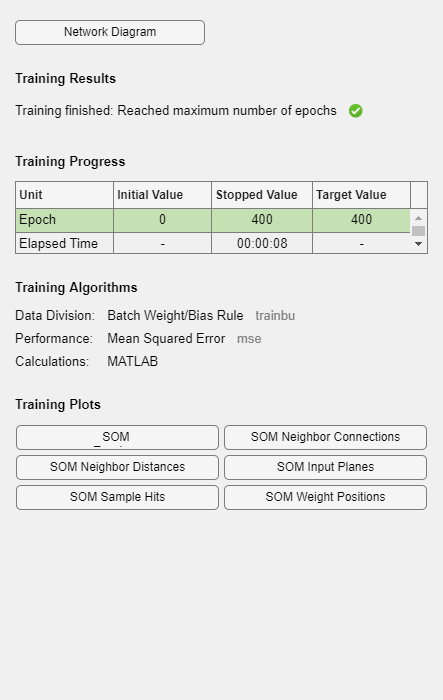

% SOM parameters
dimensions   = [10 10]; % SOM dimensions
topologyFcn  = "gridtop";       % topology function
distanceFcn  = "mandist";       % distance function
initNeighbor = 5;  % initial neighborhood size
coverSteps   = 200; % number of training steps for initial covering

 

% define 2D net
net2 = selforgmap(dimensions,coverSteps,initNeighbor,topologyFcn,distanceFcn);

% train
[net2,Y] = train(net2,P);

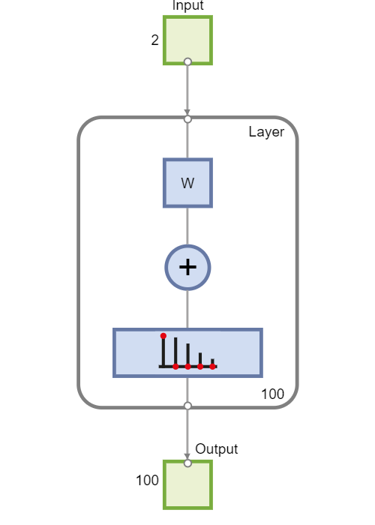

% view net
view(net2)

**Plot 2D-SOM results**

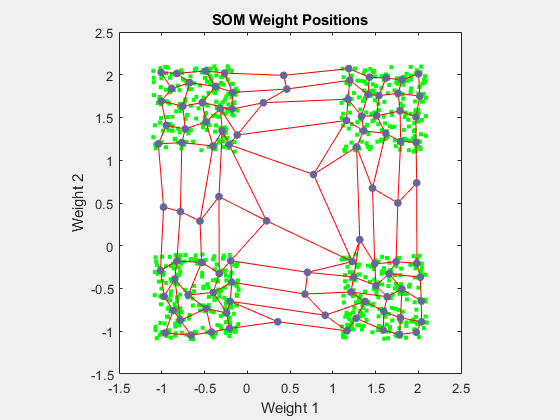

% plot input data and SOM weight positions
plotsompos(net2,P);

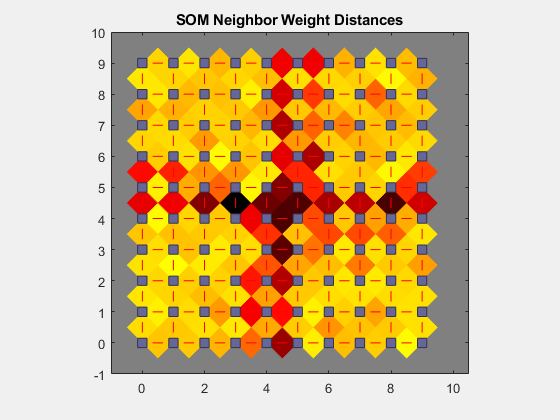

% plot SOM neighbor distances
plotsomnd(net2);

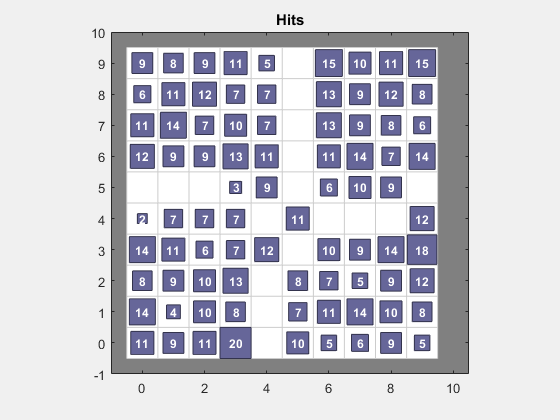

% plot for each SOM neuron the number of input vectors that it classifies
plotsomhits(net2,P);

% close all windows
close all force

## PowerPoint presentation

[NN7a_SOM.pptx](matlab:open('./NN7a_SOM.pptx'))